%%LQG lazo cerrado
A=[0 1 0; 0 0 1;0 -2 -3];
B=[0;0;1];
C=[1 0 0];
D=0;
%1er paso LQR
Q=diag([1000;1;1]);
R=0.001;
K=lqr(A,B,Q,R);
Kr = inv(-(C-D*K)*(A-B*K)^-1*B+D)

Kr = 1.0000e+03


%2do paso LQG
Gw=eye(3); %Matriz de dinamica de ruido
Qw=0.01*eye(3) %Covarianza de w

Qw =     0.0100         0         0
         0    0.0100         0
         0         0    0.0100


Vv=0.0001*eye(1) %Covarianza de v

Vv = 1.0000e-04

L=lqe(A,Gw,C,Qw,Vv)

L =    10.6229
    6.4232
   -3.0990



%3er paso, Cerrar el Lazo
ACL=[A -B*K; L*C A-B*K-L*C]

ACL = 1.0e+03 *

         0    0.0010         0         0         0         0
         0         0    0.0010         0         0         0
         0   -0.0020   -0.0030   -1.0000   -0.2814   -0.0366
    0.0106         0         0   -0.0106    0.0010         0
    0.0064         0         0   -0.0064         0    0.0010
   -0.0031         0         0   -0.9969   -0.2834   -0.0396


BCL=[B*Kr; B*Kr]

BCL = 1.0e+03 *

         0
         0
    1.0000
         0
         0
    1.0000


CCL=[C -D*K]

CCL =      1     0     0     0     0     0


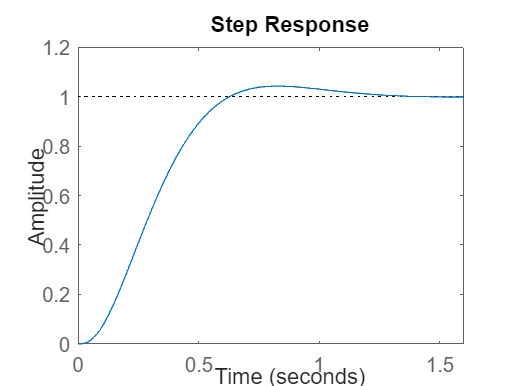

DCL=[D*Kr];

GCL=ss(ACL,BCL,CCL,DCL);
step(GCL)